# Interpolare Hermite

## Diferente Divizate. Interpolare Lagrange cu formula Newton

clf; hold on; grid on;
x=[1 2 3 4 5];
f=[14 2 17 23 13];
X=linspace(0,6,1000);

dif=dif_div(x, f)

dif =                         14                       -12                      13.5                        -6          1.20833333333333
                         2                        15                      -4.5         -1.16666666666667                       NaN
                        17                         6                        -8                       NaN                       NaN
                        23                       -10                       NaN                       NaN                       NaN
                        13                       NaN                       NaN                       NaN                       NaN


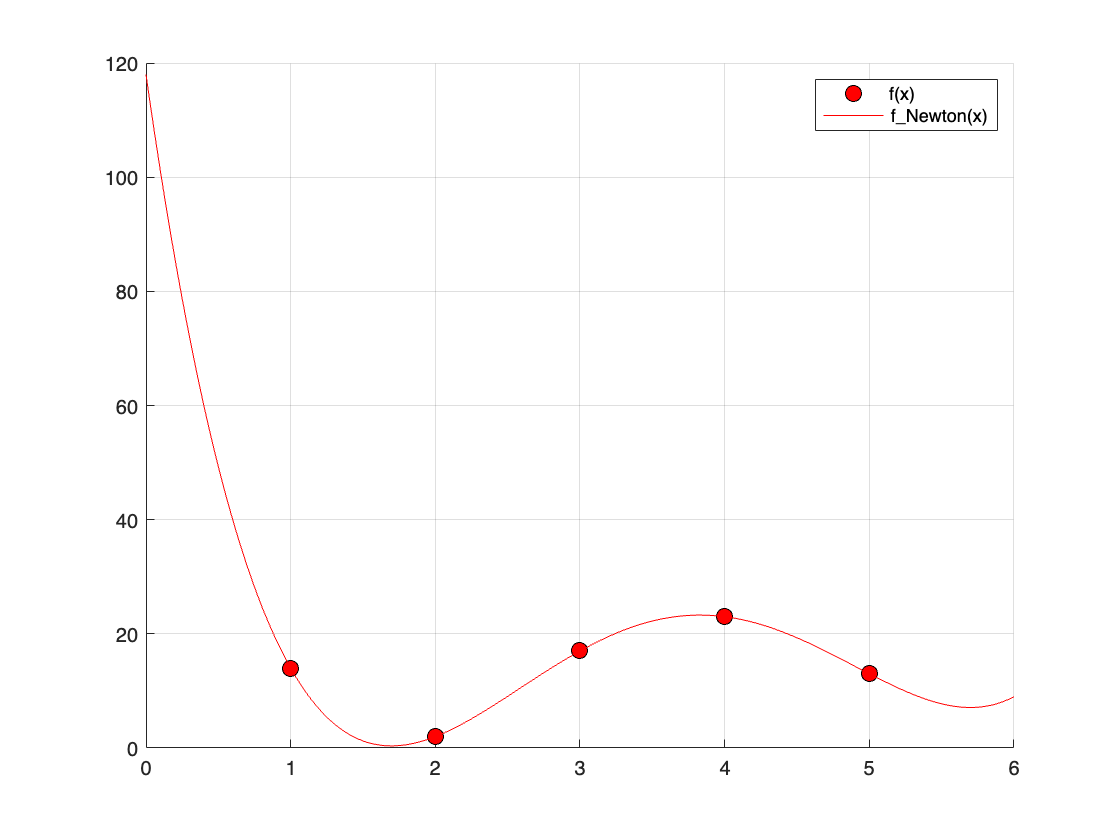

f_Newton=Newton_interpolare(x, f, X);
plot(x, f, 'ok', 'markerfacecolor', 'r', 'markersize', 8)
plot(X, f_Newton, 'r')
legend("f(x)", "f\_Newton(x)")

## Diferente Divizate Duble. Interpolare Hermite.

clf; hold on; grid on;
x=[0 3];
f=[10 13];
df=[5 7];
X=linspace(-1,4,1000);
dif=dif_div_duble(x, f, df)

dif =                         10                         5         -1.33333333333333          1.11111111111111
                        10                         1                         2                       NaN
                        13                         7                       NaN                       NaN
                        13                       NaN                       NaN                       NaN


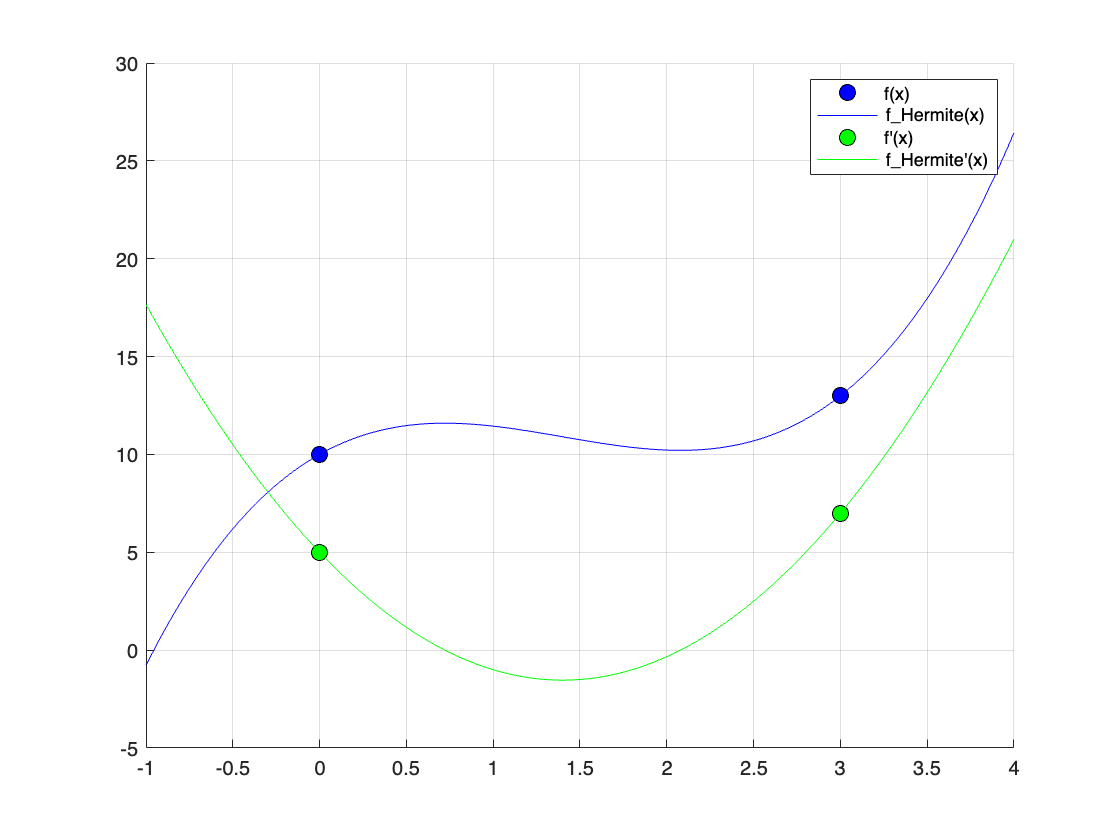

[f_Hermite, df_Hermite]=Hermite_interpolare(x, f, df, X);
plot(x, f, 'ok', 'markerfacecolor', 'b', 'markersize', 8);
plot(X, f_Hermite, 'b')
plot(x, df, 'ok', 'markerfacecolor', 'g', 'markersize', 8)
plot(X, df_Hermite, 'g')
legend("f(x)", "f\_Hermite(x)", "f'(x)", "f\_Hermite'(x)")